Zadanie 1


clear all; close all;

syms t t1 t2 offset x 

T0 = 1.0;		% okres
t1 = -0.5; 
t2 = t1+T0;
offset = T0/4;

f0 = 1/T0;		% czestotliwosc
w0 = 2*pi*f0;	% pulsacja

% granice ca³kowania
BND = [t1,t2] + offset; 

x = triangularPulse(t1,0,t2,t-offset)-0.5;
idx = find(diff(sign(x)) ~= 0);
value=x(idx)

$$value = \mathrm{triangularPulse}\left(-\frac{1}{2},0,\frac{1}{2},t-\frac{1}{4}\right)-\frac{1}{2}$$

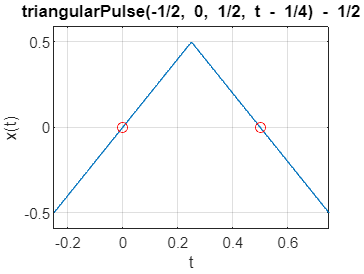

figure;

ezplot(x,BND); 
grid on; 
ylabel('x(t)');
hold on
plot([0,0.5],0,'ro')

Zadnie 2

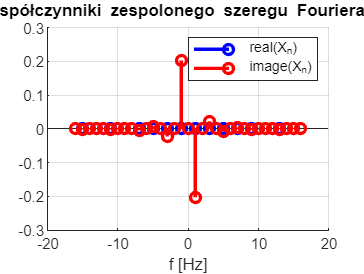

NT = 16;
X=[];
ind = -NT : NT;
for n = ind
Xn = (1/T0)*int(x*exp(-i*w0*n*t),t,BND);
X(n + NT + 1) = Xn;
end
figure; hold on;
stem(ind*f0,real(X),'b','LineWidth',2);
xlabel('f [Hz]')
stem(ind*f0,imag(X),'r','LineWidth',2);
grid on
legend('real(X_n)','image(X_n)','Location','NorthEast')
title('Współczynniki zespolonego szeregu Fouriera X_n')

Zadanie 3

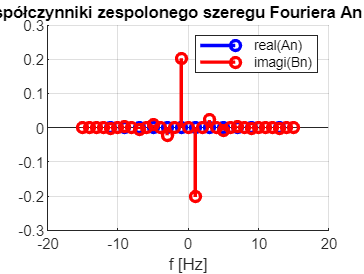

NT = 15;
An = zeros(1, 2 * NT + 1); % wektor do przechowywania współczynników wartości reczywistych
Bn = zeros(1, 2 * NT + 1); % wektor do przechowywania współczynników wartości urojonych

ind = -NT : NT;
for i = ind
An(i+NT+1)=(1/T0)*int(x*cos(-w0*i*t),t,BND);
Bn(i+NT+1)=(1/T0)*int(x*sin(-w0*i*t),t,BND);
end
An;
Bn;

figure
hold on
stem(ind*f0,An,'b','LineWidth',2);
xlabel('f [Hz]')
stem(ind*f0,Bn,'r','LineWidth',2);
grid on
legend('real(An)', 'imagi(Bn)', 'Location', 'NorthEast');
title('Współczynniki zespolonego szeregu Fouriera An i Bn')

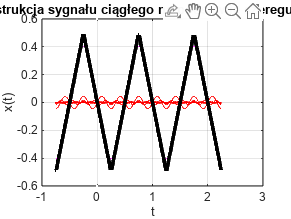

a=An;
b=Bn;
step = (BND(2) - BND(1))/1000;
tt = [BND(1)-0.5*T0: step: BND(2) + 1.5*T0];%jeżeli chce się uzyskać wykres 
xx = zeros(1,length(tt));
xx = xx + a(NT+1); % skladowa stala
figure
plot(tt,xx,'m'); grid on, hold on;
plot([0,0],[-0.6,0.6],'w.')
xlabel('t'); ylabel('x(t)');
pause(0.5)
for n = 1 :NT
xx_n = 2*(a(NT+n+1)*cos(w0*n*tt) + b(NT+n+1)*sin(w0*n*tt));
xx = xx + xx_n;
plot(tt,xx_n,'r'); plot(tt,xx,'m');
title(sprintf('n = %d',n+1)); pause(0.5)
end
plot(tt,xx,'k','LineWidth',3);
title('Rekonstrukcja sygnału ciągłego na podstawie szeregu Fouriera')